# Lysosome Display

This live script was used to generate the figures of taste cells with their lysosome 

NOTE: The tables used in this script are generated and/or updated in the companion [**lysosome_get_tables**](matlab:open('./lysosome_get_tables.mlx')) live script

**Additional Requirements:**

- The MatGeom toolbox:  [https://github.com/mattools/matGeom](https://github.com/mattools/matGeom) 

## Initialize functions and load data

close all
clearvars -except paths proj
[VL, idT, cellT, dyingT,lysT] = loadProjectTables(paths);

### Update Cell Names

Disconnect between Mesh Name (stored in cellT vs Trace Name (stored in idT) due to apical bits and cell mesh merging in generate cell mesh script

cellT.Cell = replace(cellT.Cell,"TB3_TC01","TB3_TC01_dying_cw");
cellT.Cell = replace(cellT.Cell,"TB2_TCdying01","TB2_TCdying-01_cw");
cellT.Cell = replace(cellT.Cell,"TB2_TCdying02","TB2_TCdying-02_cw");

## Display

### Set Polarity

cells are randomly orientated after  MatGeom Align to surface function. Polarity helps control for this stochastic process. 

### Plot Cells Lysosomes Overlays

Organize Cells in one figure (using nexttile)

#### Use Patch

plot_cellT(VL, cellT,'patch');

- Slower

### Use alphaShape

cellT = sortrows(cellT,"VolMan");
mmfig
hp = plot_cellT(VL, cellT,'alphaShape');

### Plot by selected cellT row

mmfig; % create new figure

#### Select Row

clf; % clear figure
rows = 18; % select row
hp = plot_cellT(VL, cellT(rows,:),'alphaShape',false);

#### Change plot appearance

Rendering...
1. TB1_IMMCell09_CM_ry
2. TB1_IMMcell08_CM_RKJ
3. TB2 Nucleus_26_cw_IV-ry
4. TB2_T4C-01_cw
5. TB1_AP31_EM
6. TB2_t3cell02_CM_RSL
7. TB2_T3Cell07_cm_RSL
8. TB2_T3C-08_cw
9. TB2_T3C-17_cw
10. TB1_AP02_EM
11. TB2_T3C-14_FR
12. TB1_AP14_EM
13. TB2_T2C-12_cw
14. TB2_T2Cell03_CM_LES
15. TB2_T2C-09_cw
16. TB2_T2C-10_cw
17. TB1_AP38_EM
18. TB1_AP16_EM
19. TB1_AP36_EM
20. TB1_AP37_EM
21. TB2 Nucleus_04_cw_cell-ry
22. TB1_AP70_RSL
23. TB2_T1C-05_cw
24. TB2_T1C-06_cw
25. TB1_AP34_EM
26. TB3_TC01_dying_cw
27. TB2_TCdying-01_cw
28. TB2_TCdying-02_cw
29. TB1_AP44_EM
30. TB1_AP40_EM
31. TB1_AP13_EM
32. TB2_T2C-03_cw
33. TB2_T2C-01_FR
34. TB1_AP51_EM


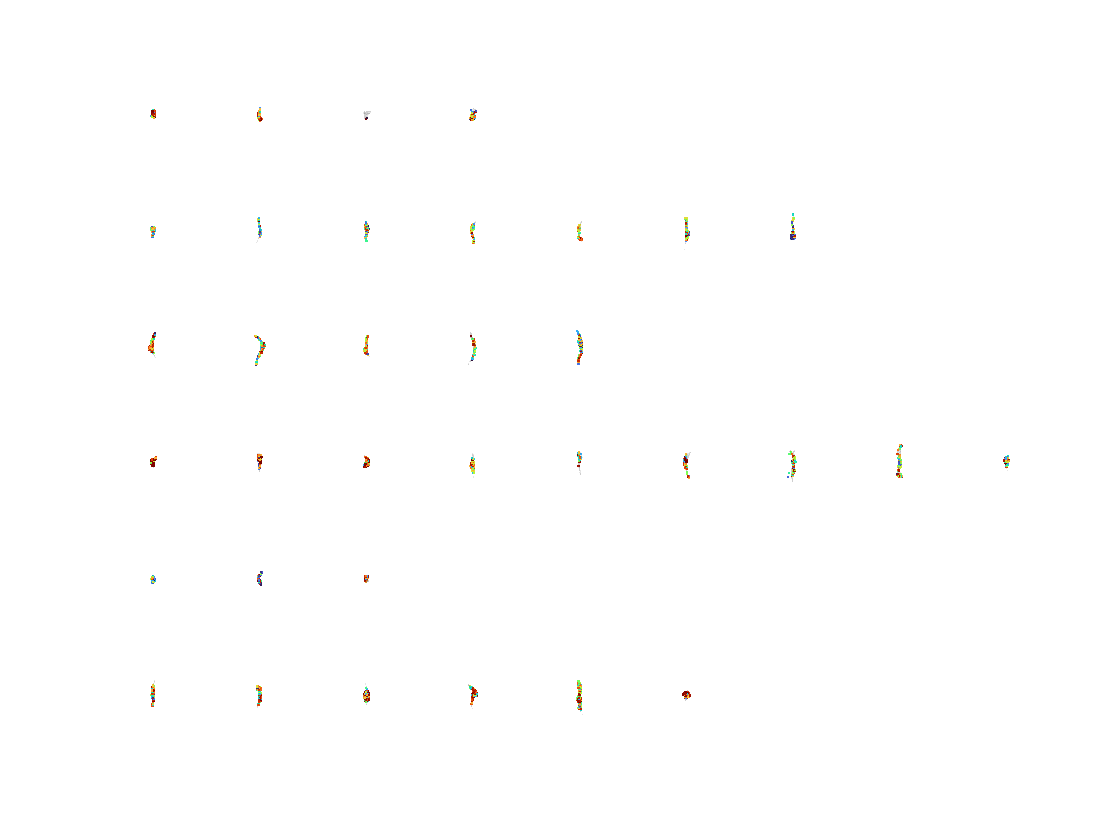

hp.EdgeColor = 'k'

hp.FaceColor = 'g';
hp.FaceAlpha = 0.9

### Export Figures

exportgraphics(gcf,fullfile(project_folder,"Figures","AP13vAP14.png"),Resolution=300)

exportgraphics(gcf,fullfile(project_folder,"Figures","colorbar.pdf"))

#### Get stats on COI

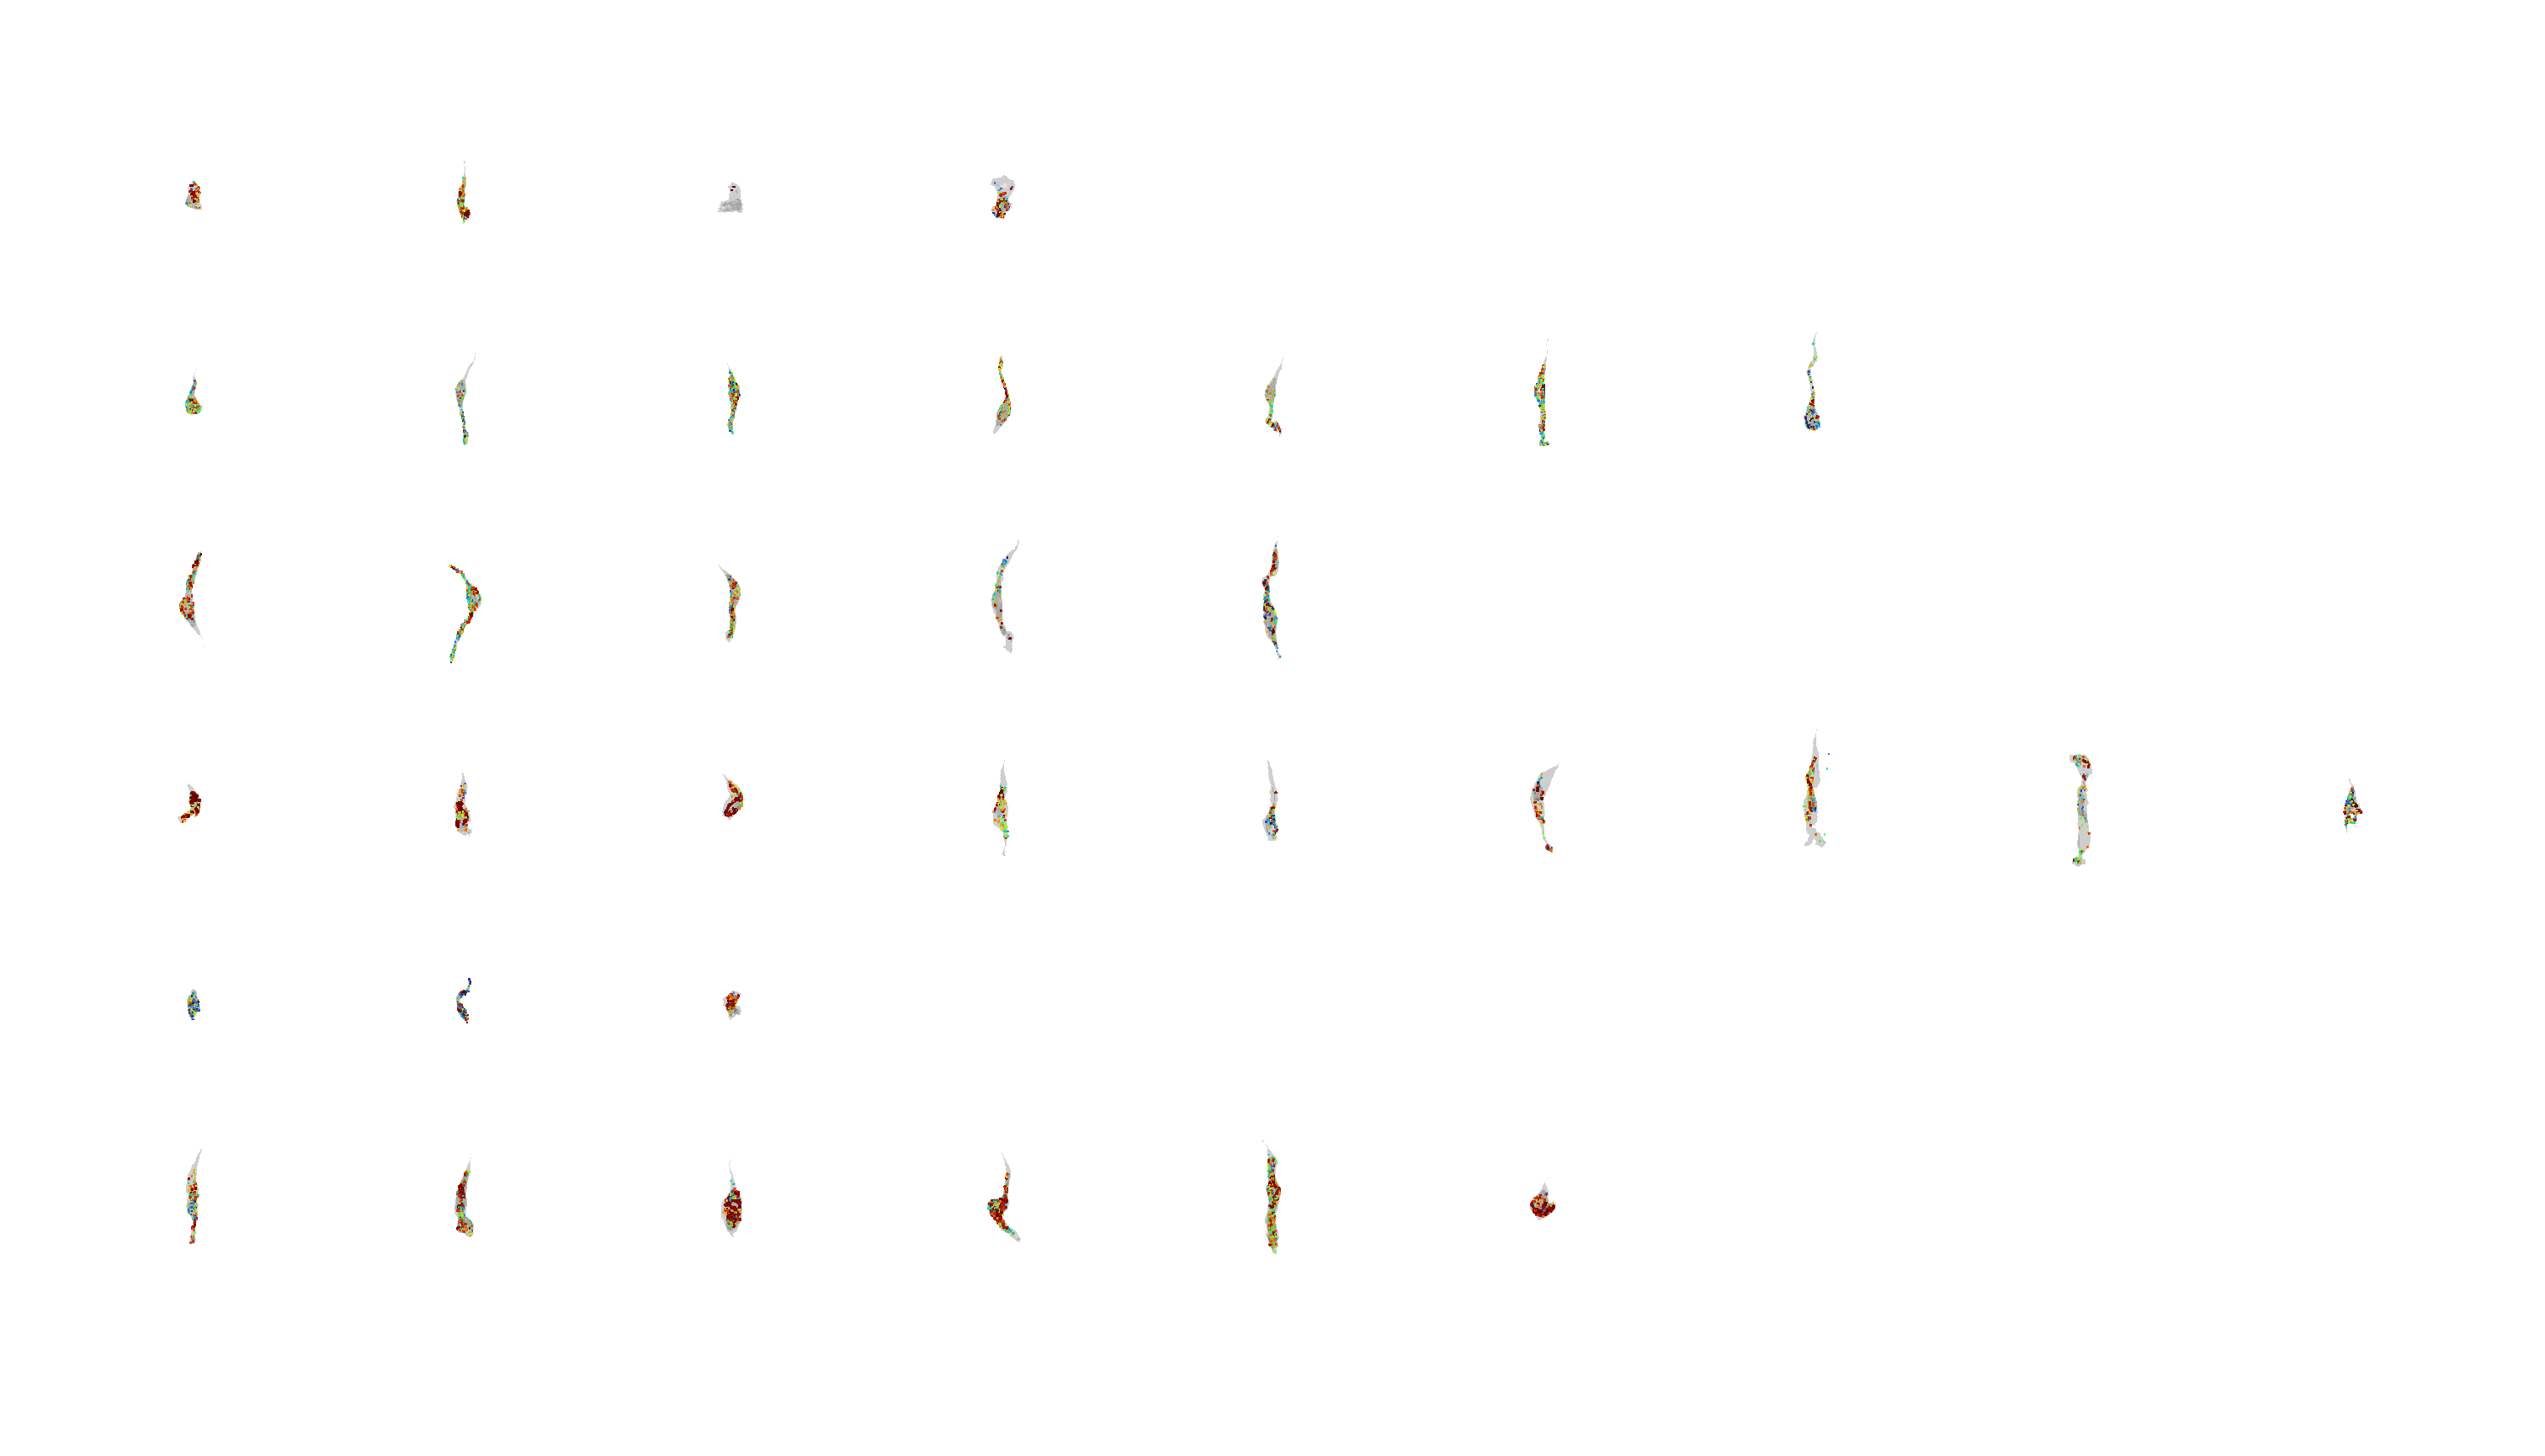

la = ismember(lysT.Cell,coi);

lt = lysT(la,:);

## Plot Cell Lysosomes by Cell Type

Cell type is a plotted by row in figure

### Set Polarity

- not really using this

#### Plot cells as alpha shapes

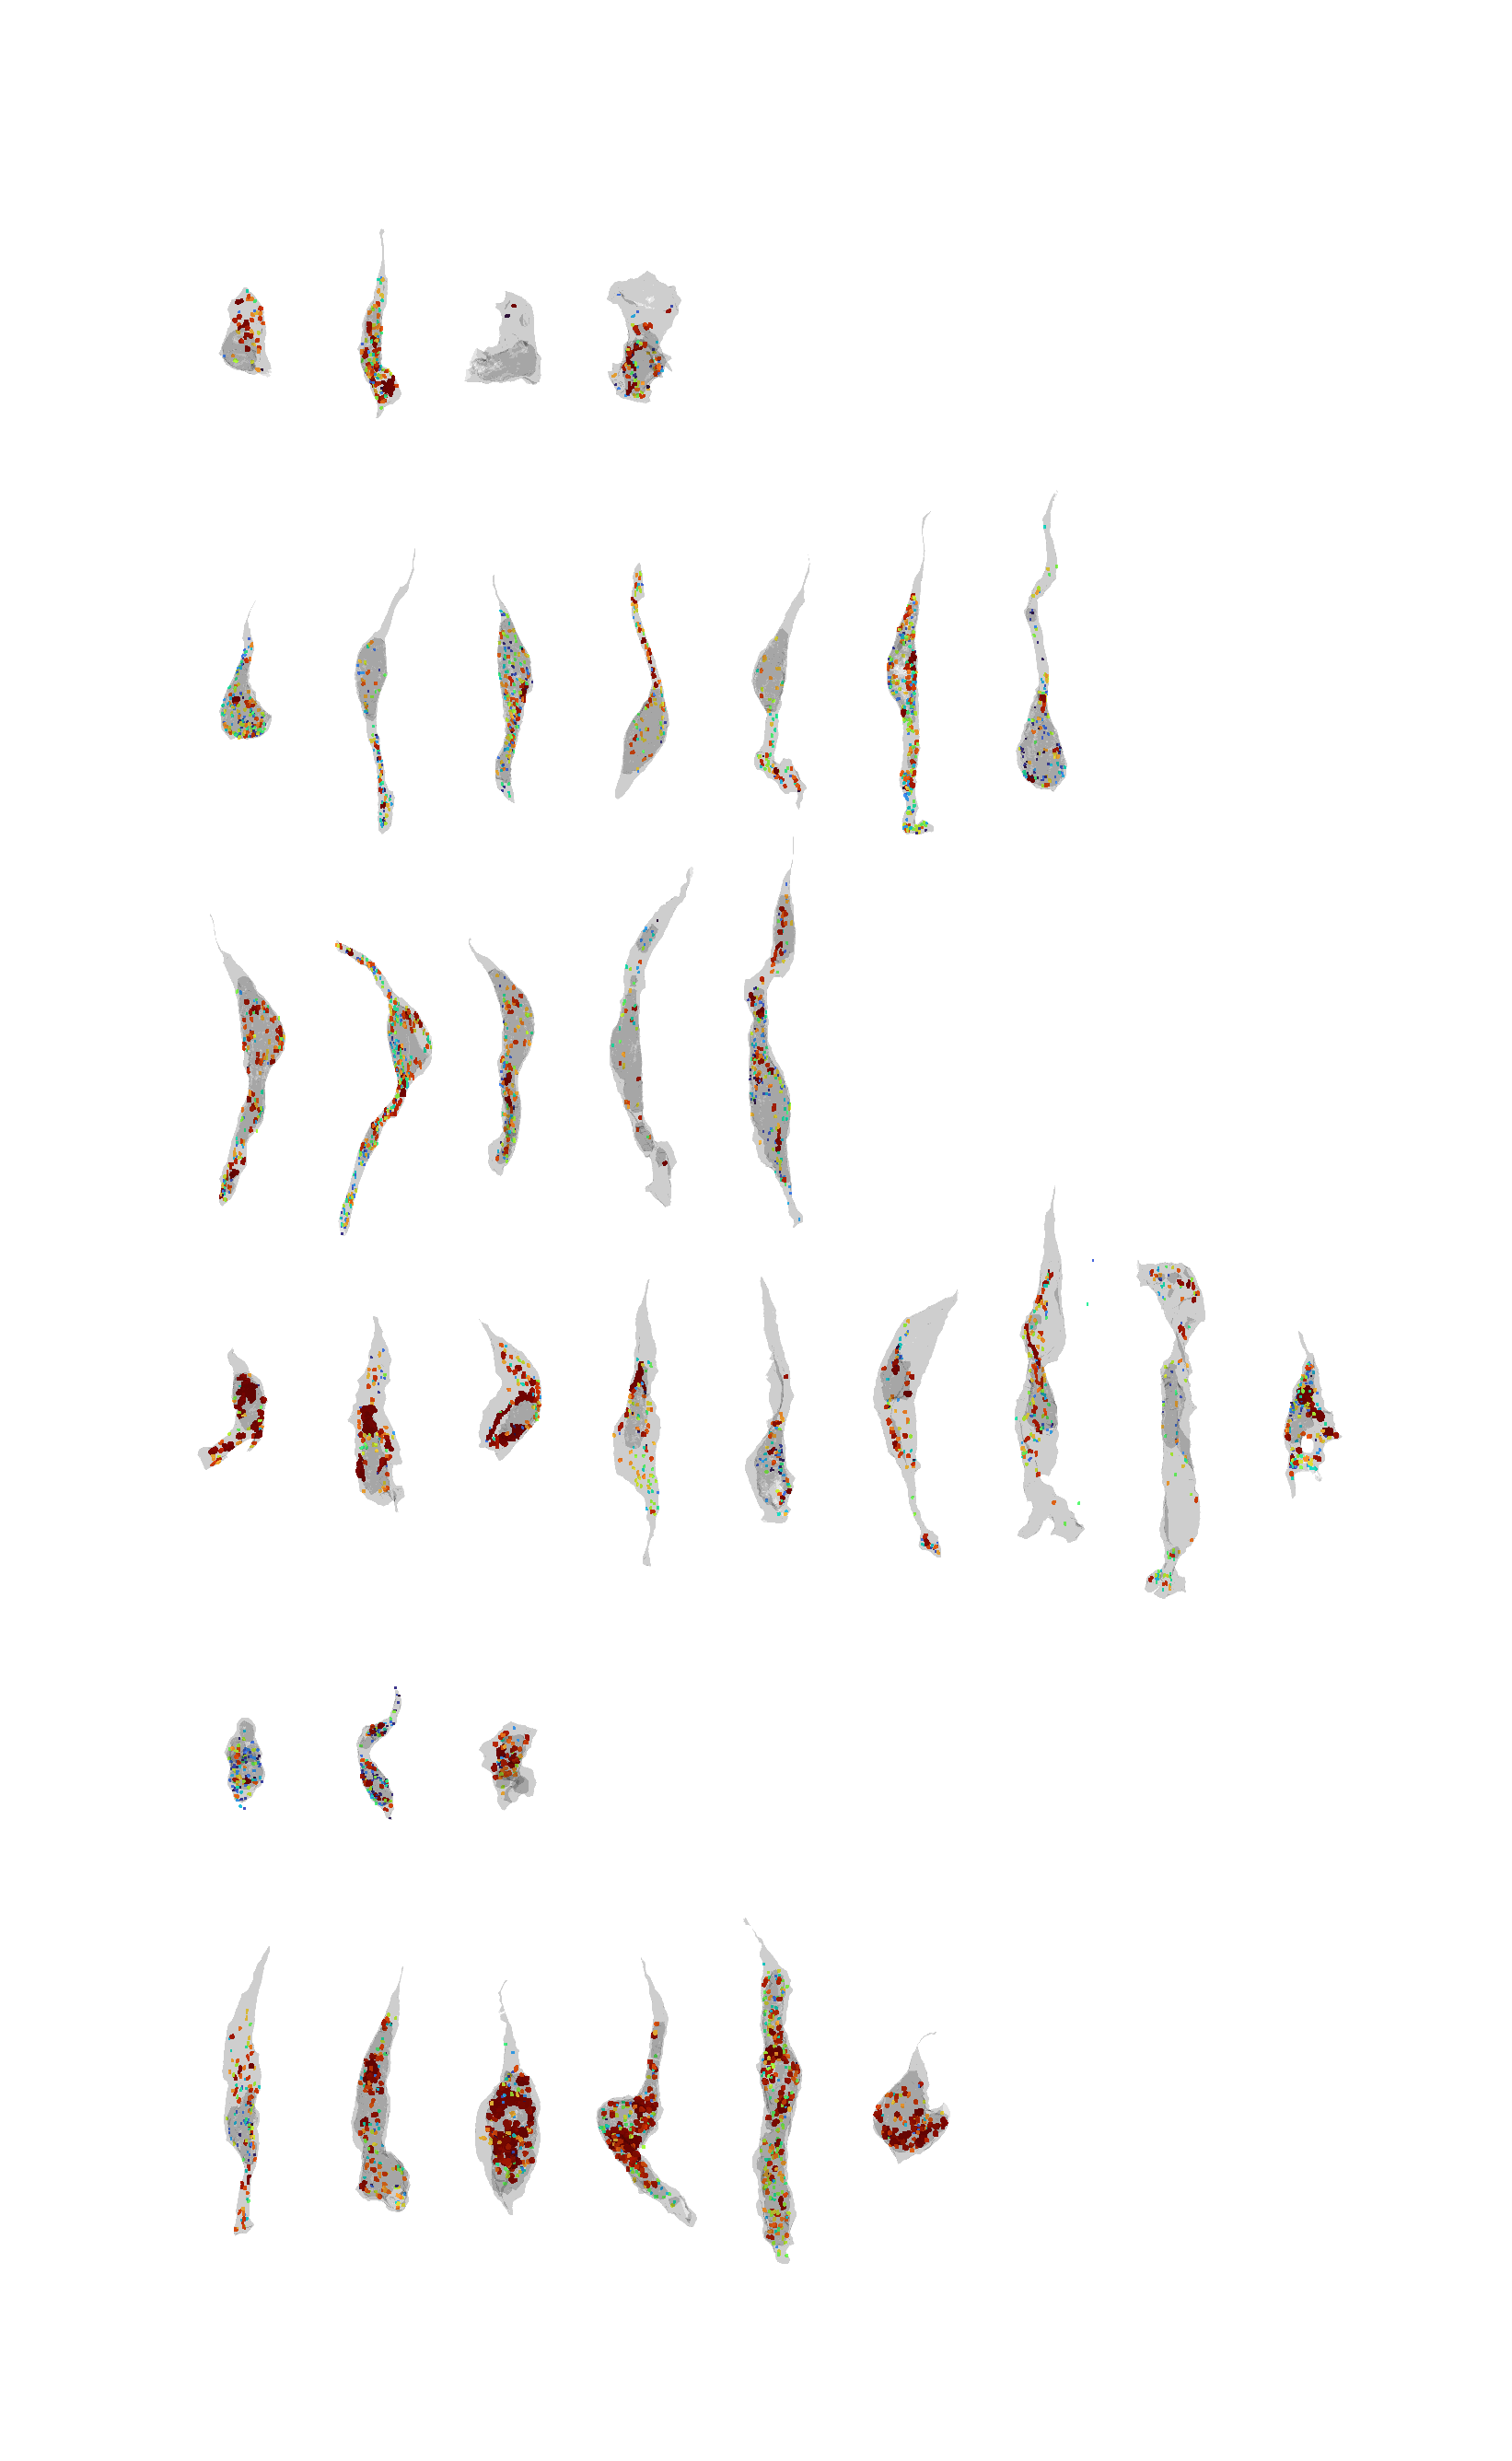

% figure(Visible="on",WindowStyle="docked")

ax = plot_cellT_tiled(VL,cellT); 

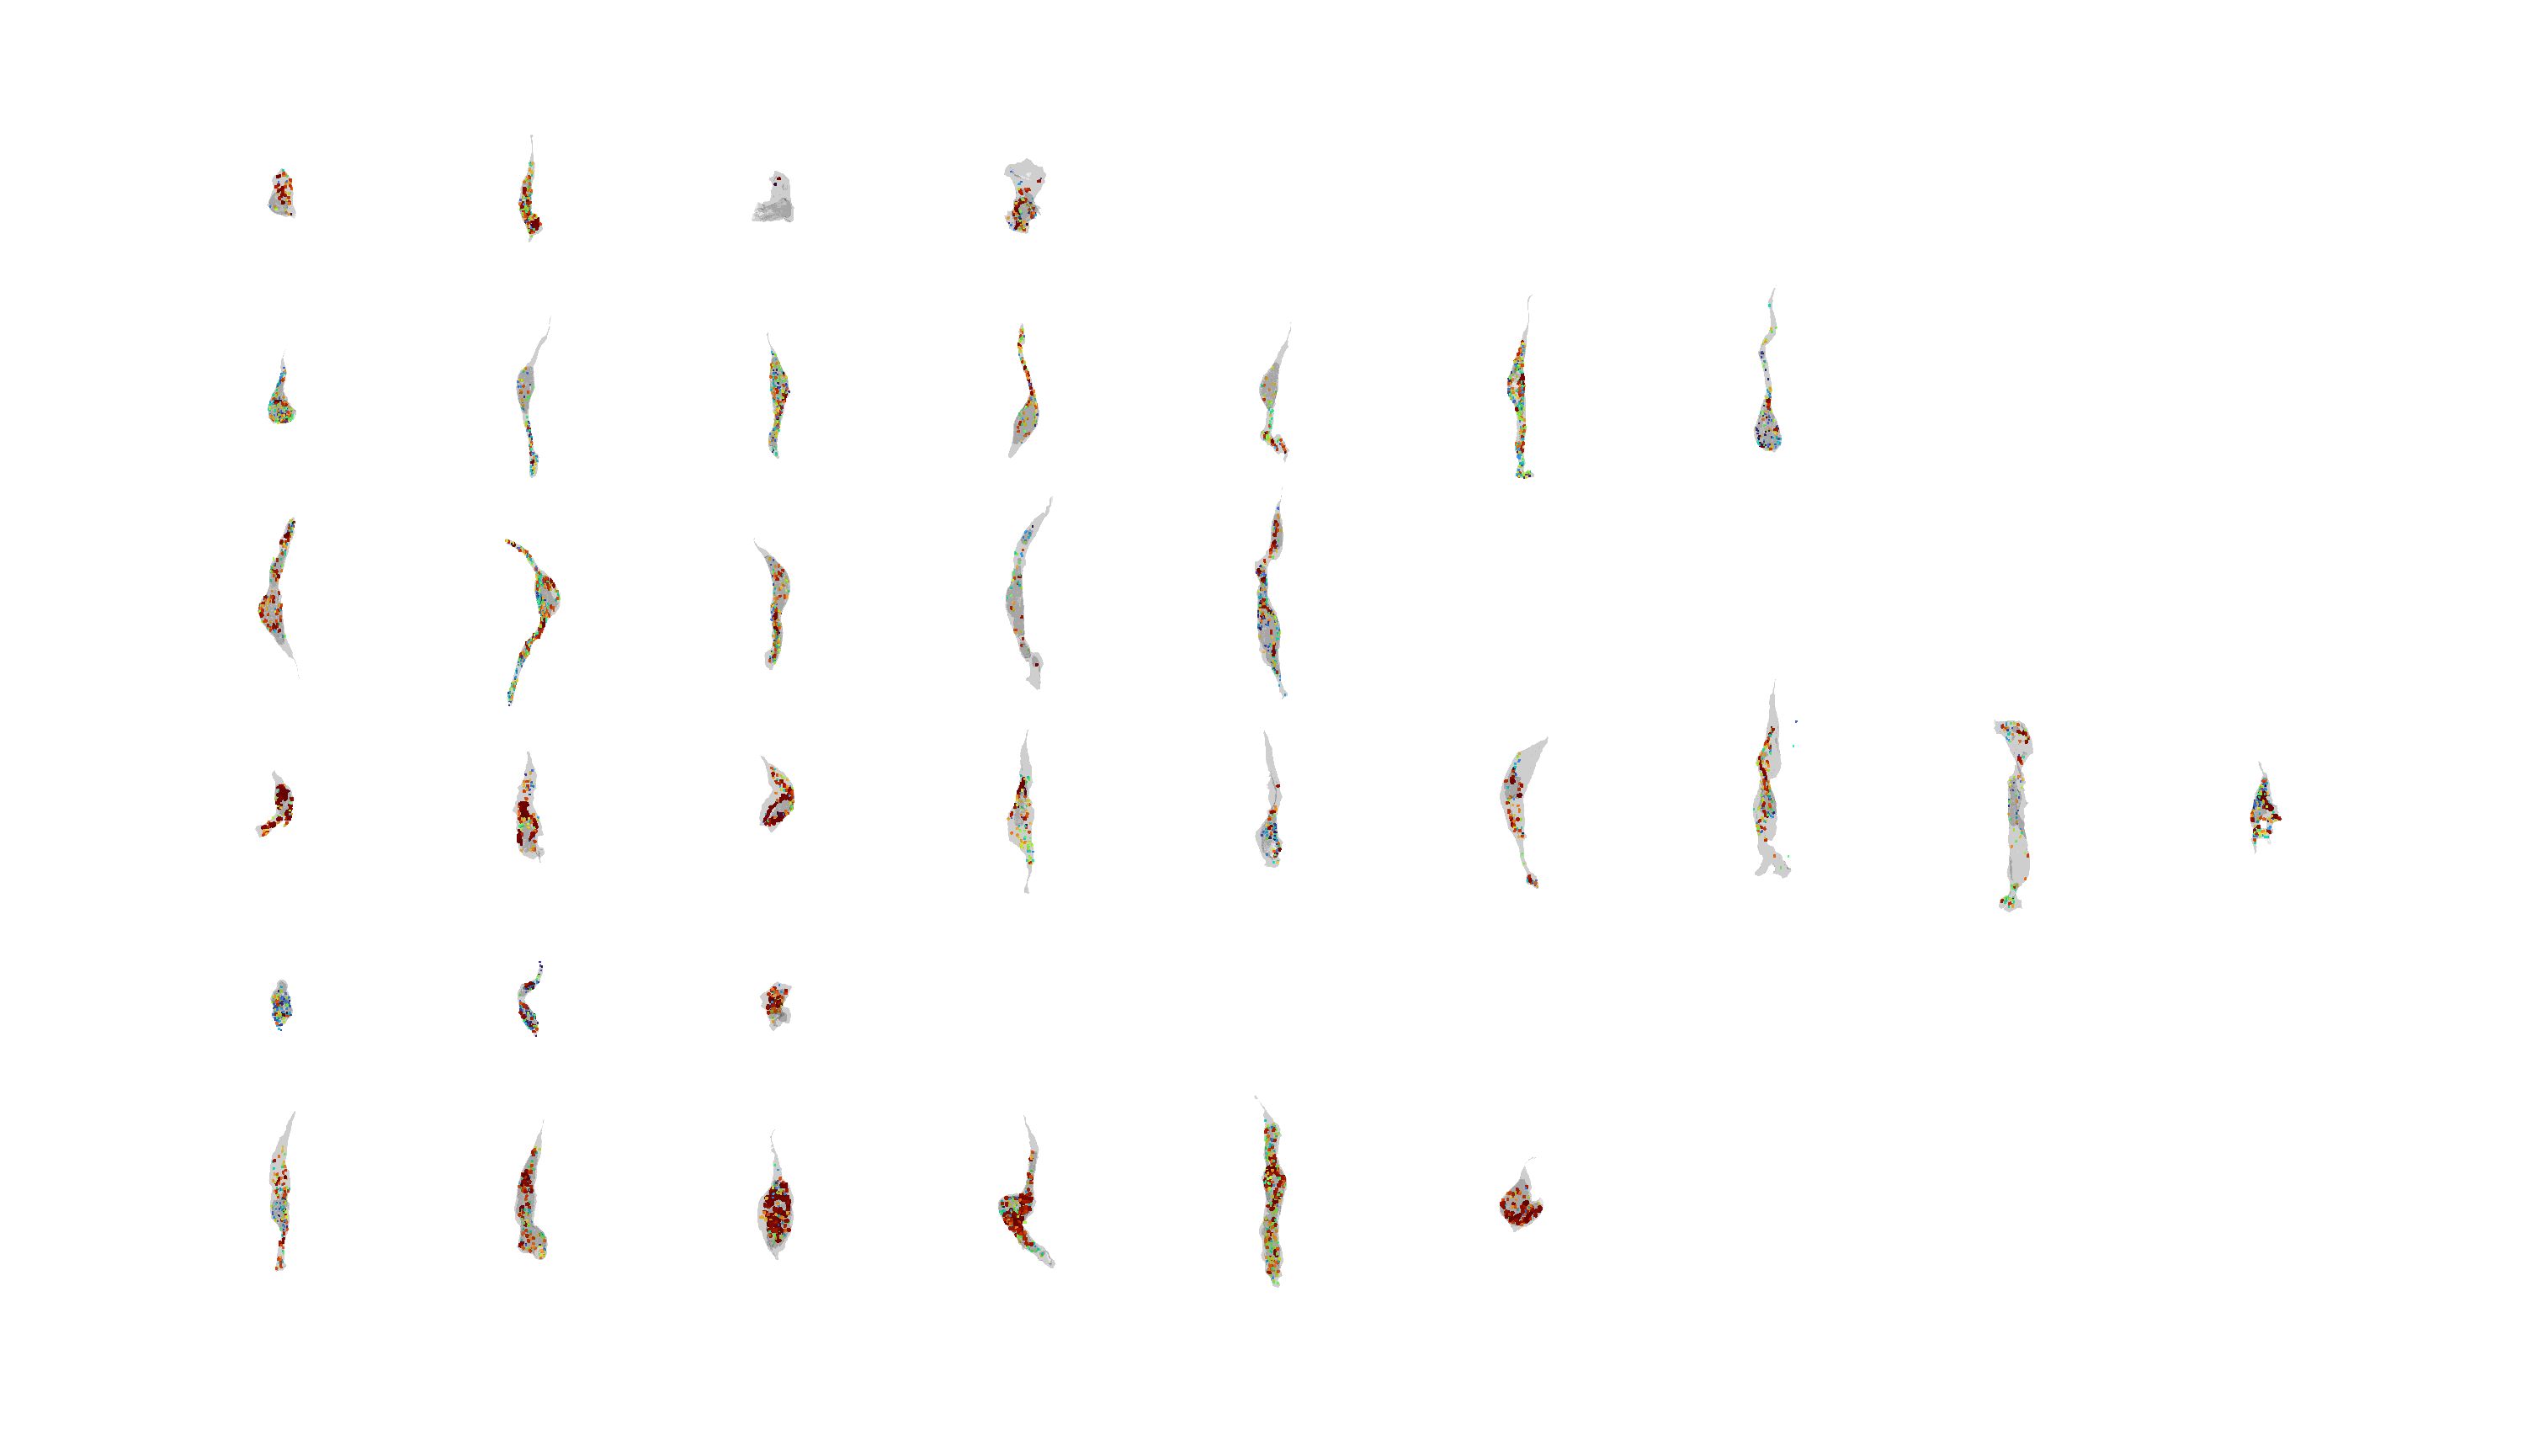

set(ax,CameraUpVector = [0 0 1])

cellT.Polarity = ones(height(cellT),1);
cellT.Polarity([3 5 6 8 10 12 14 15 16 17 18 21 23 24 25 30 32 33 34]) = -1; % set up vector
set(ax(cellT.Polarity<0), CameraUpVector = [0 0 -1])

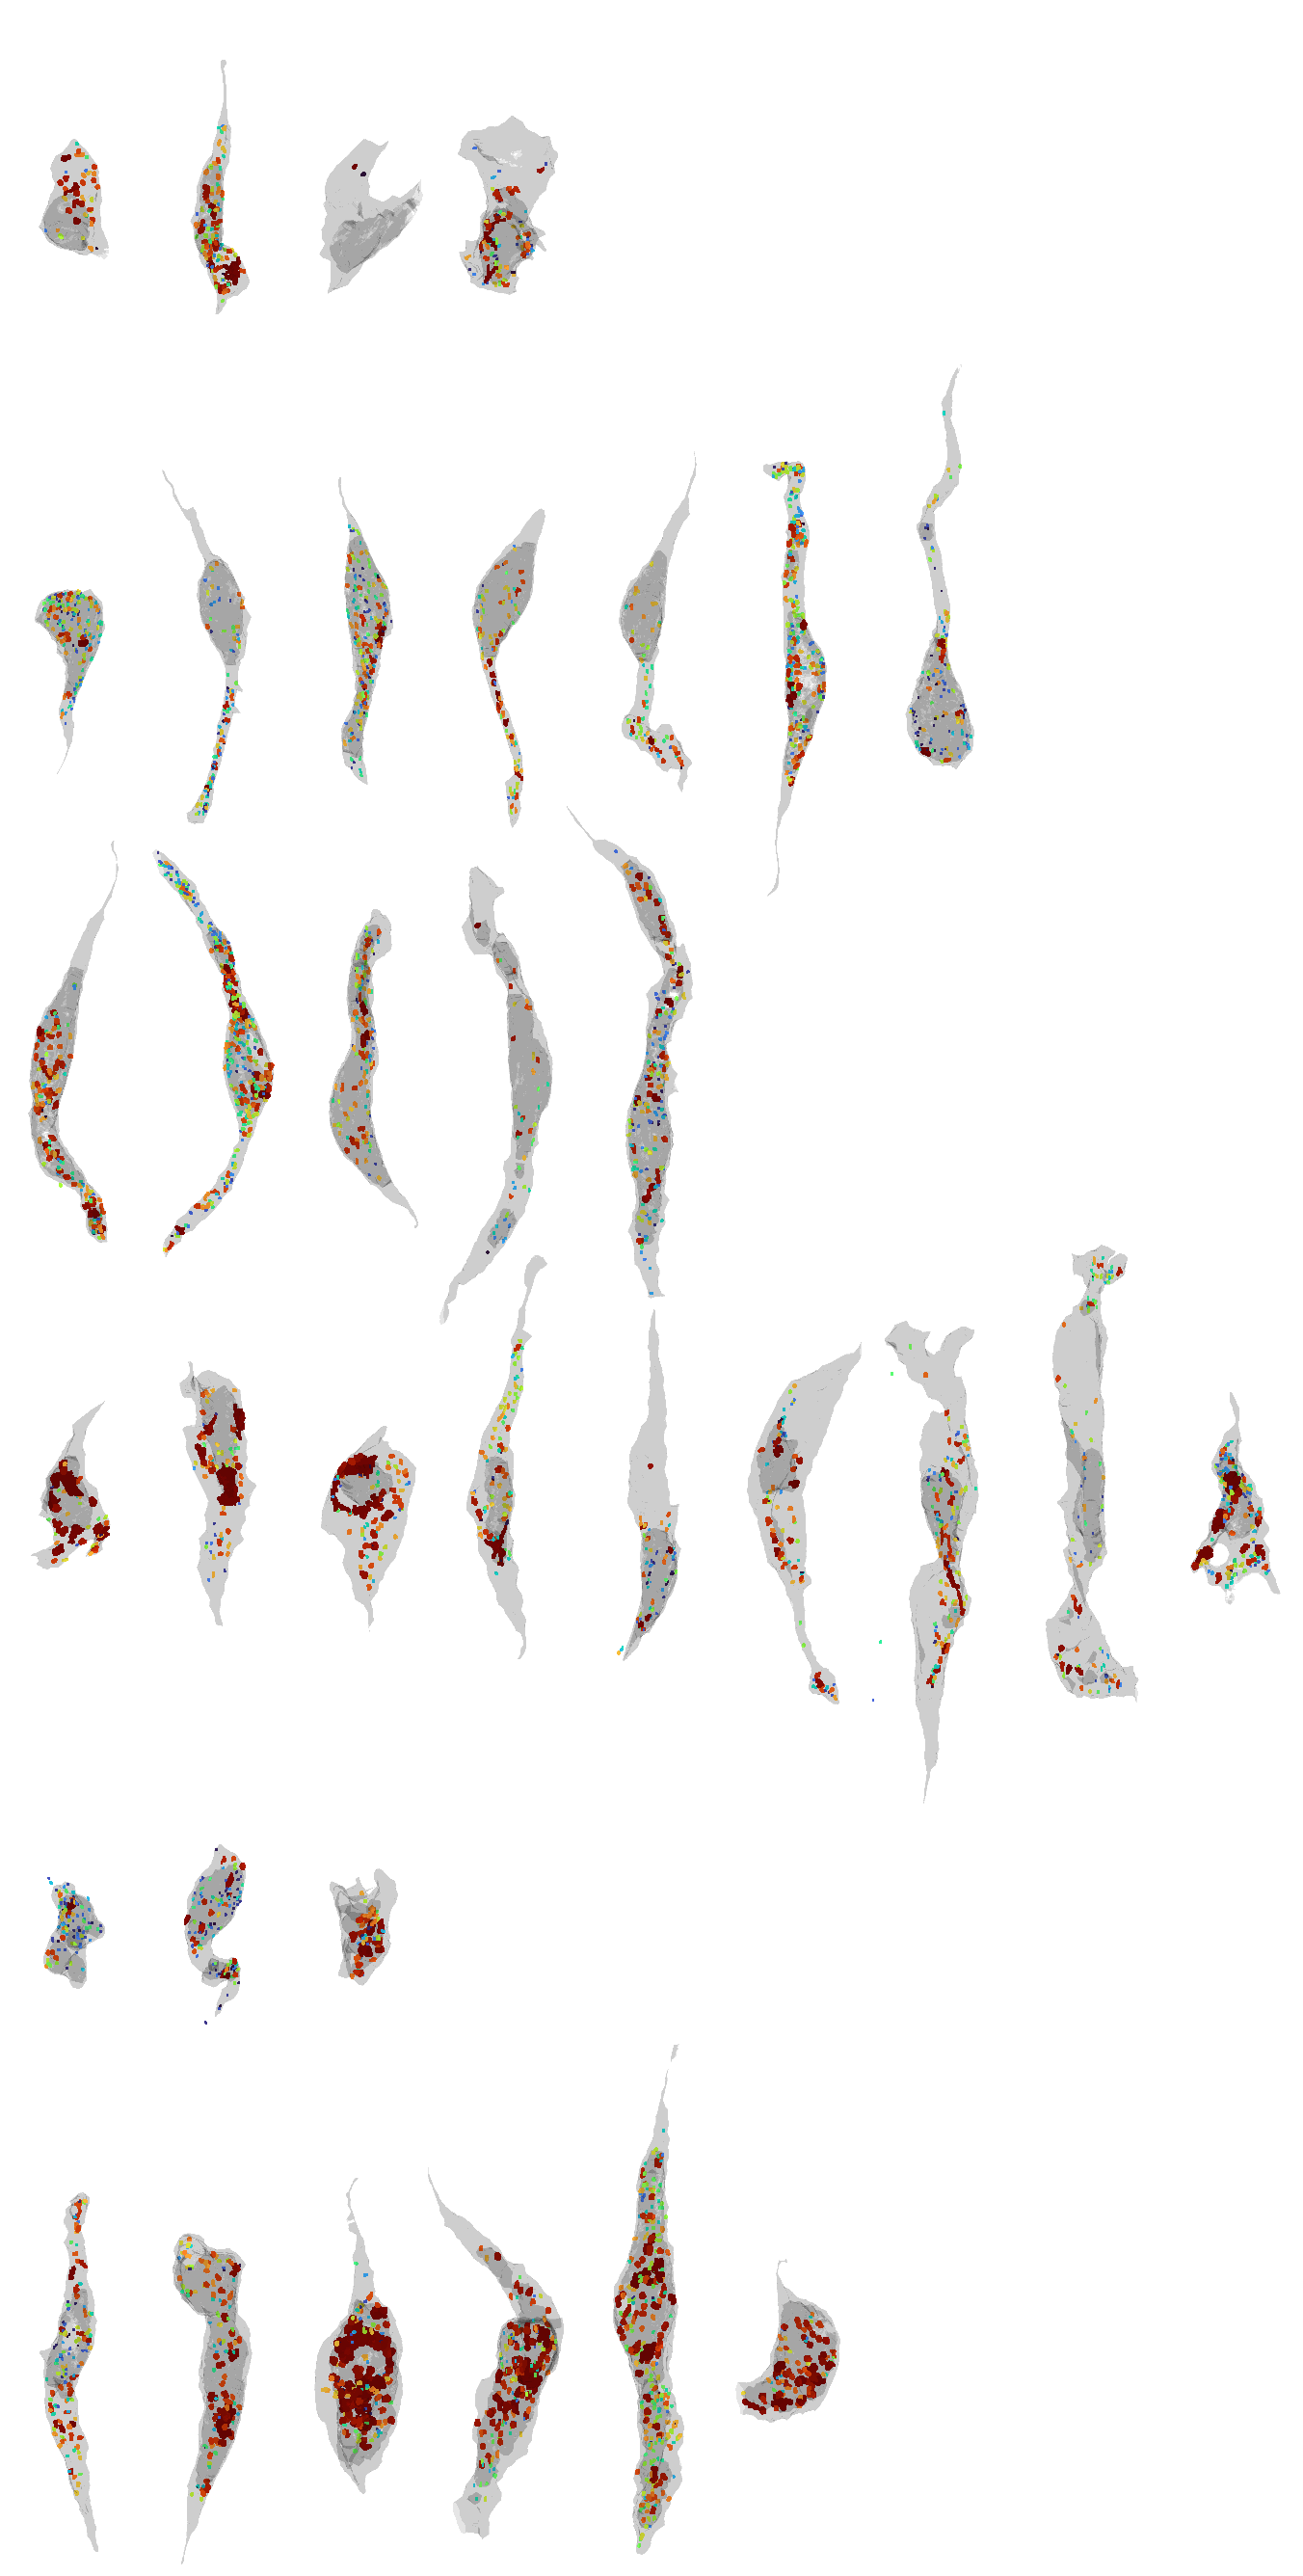

set(ax([12]),"CameraUpVector",[0 0 -1])

set(ax, CameraViewAngle=2.1)

- makes cells look larger in their axis

### Save Figures

- save as a high resolution png file

exportgraphics(gcf,fullfile(paths.project,"Lysosome Analysis","Figures","Cell-Lys-by-type.png"),Resolution=600)

## Plot Indicated Cells (and lysosomes)

Here we use the cellT table (or a subset of the table) to indicate which cells to plot

#### Create Figure

mmfig;

- TB1_AP13_EM

- TB1_AP14_EM

NOTE: cells may be plot but be too small to notice at first. Make figure larger to see them

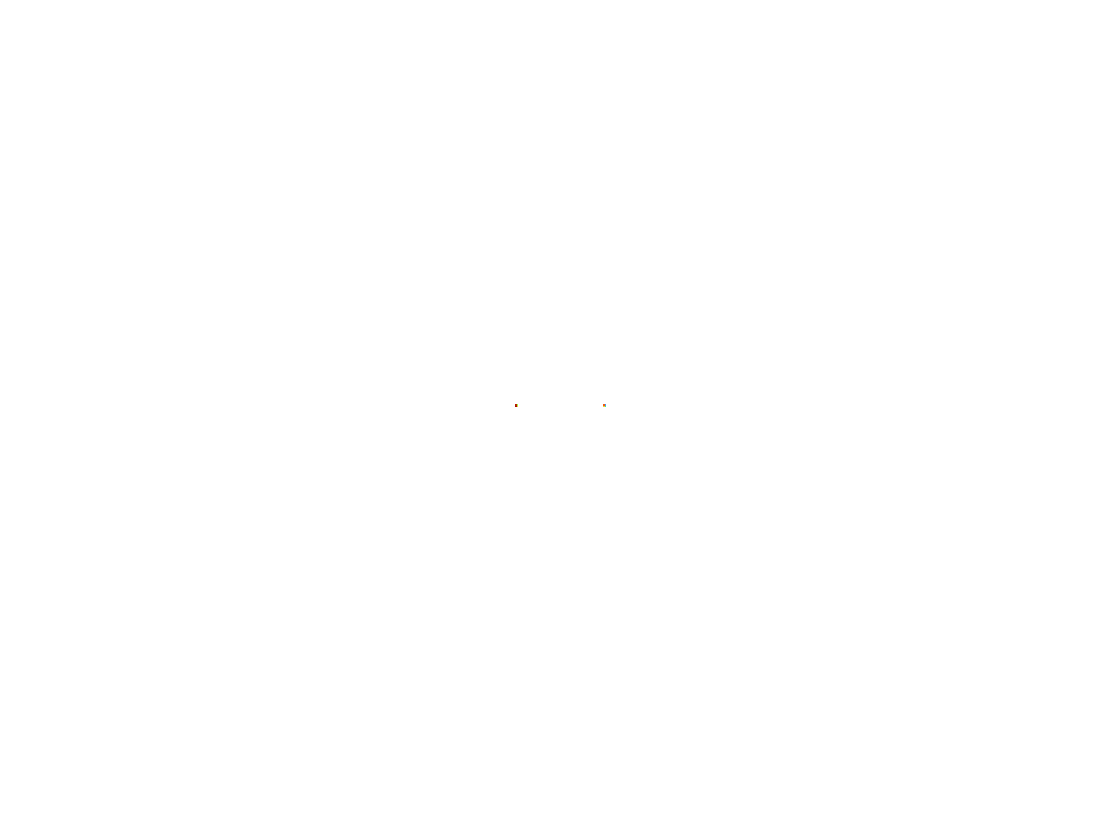

coi = ["TB1_AP13_EM" "TB1_AP14_EM"]; % cells of interest
la = ismember(cellT.Cell,coi);
rows = find(la);

hp = gobjects(2,1);

figure(Visible="on")
nexttile
hp(1) = plot_cell_mesh(VL,cellT,rows(1));
nexttile
hp(2) = plot_cell_mesh(VL,cellT,rows(2));

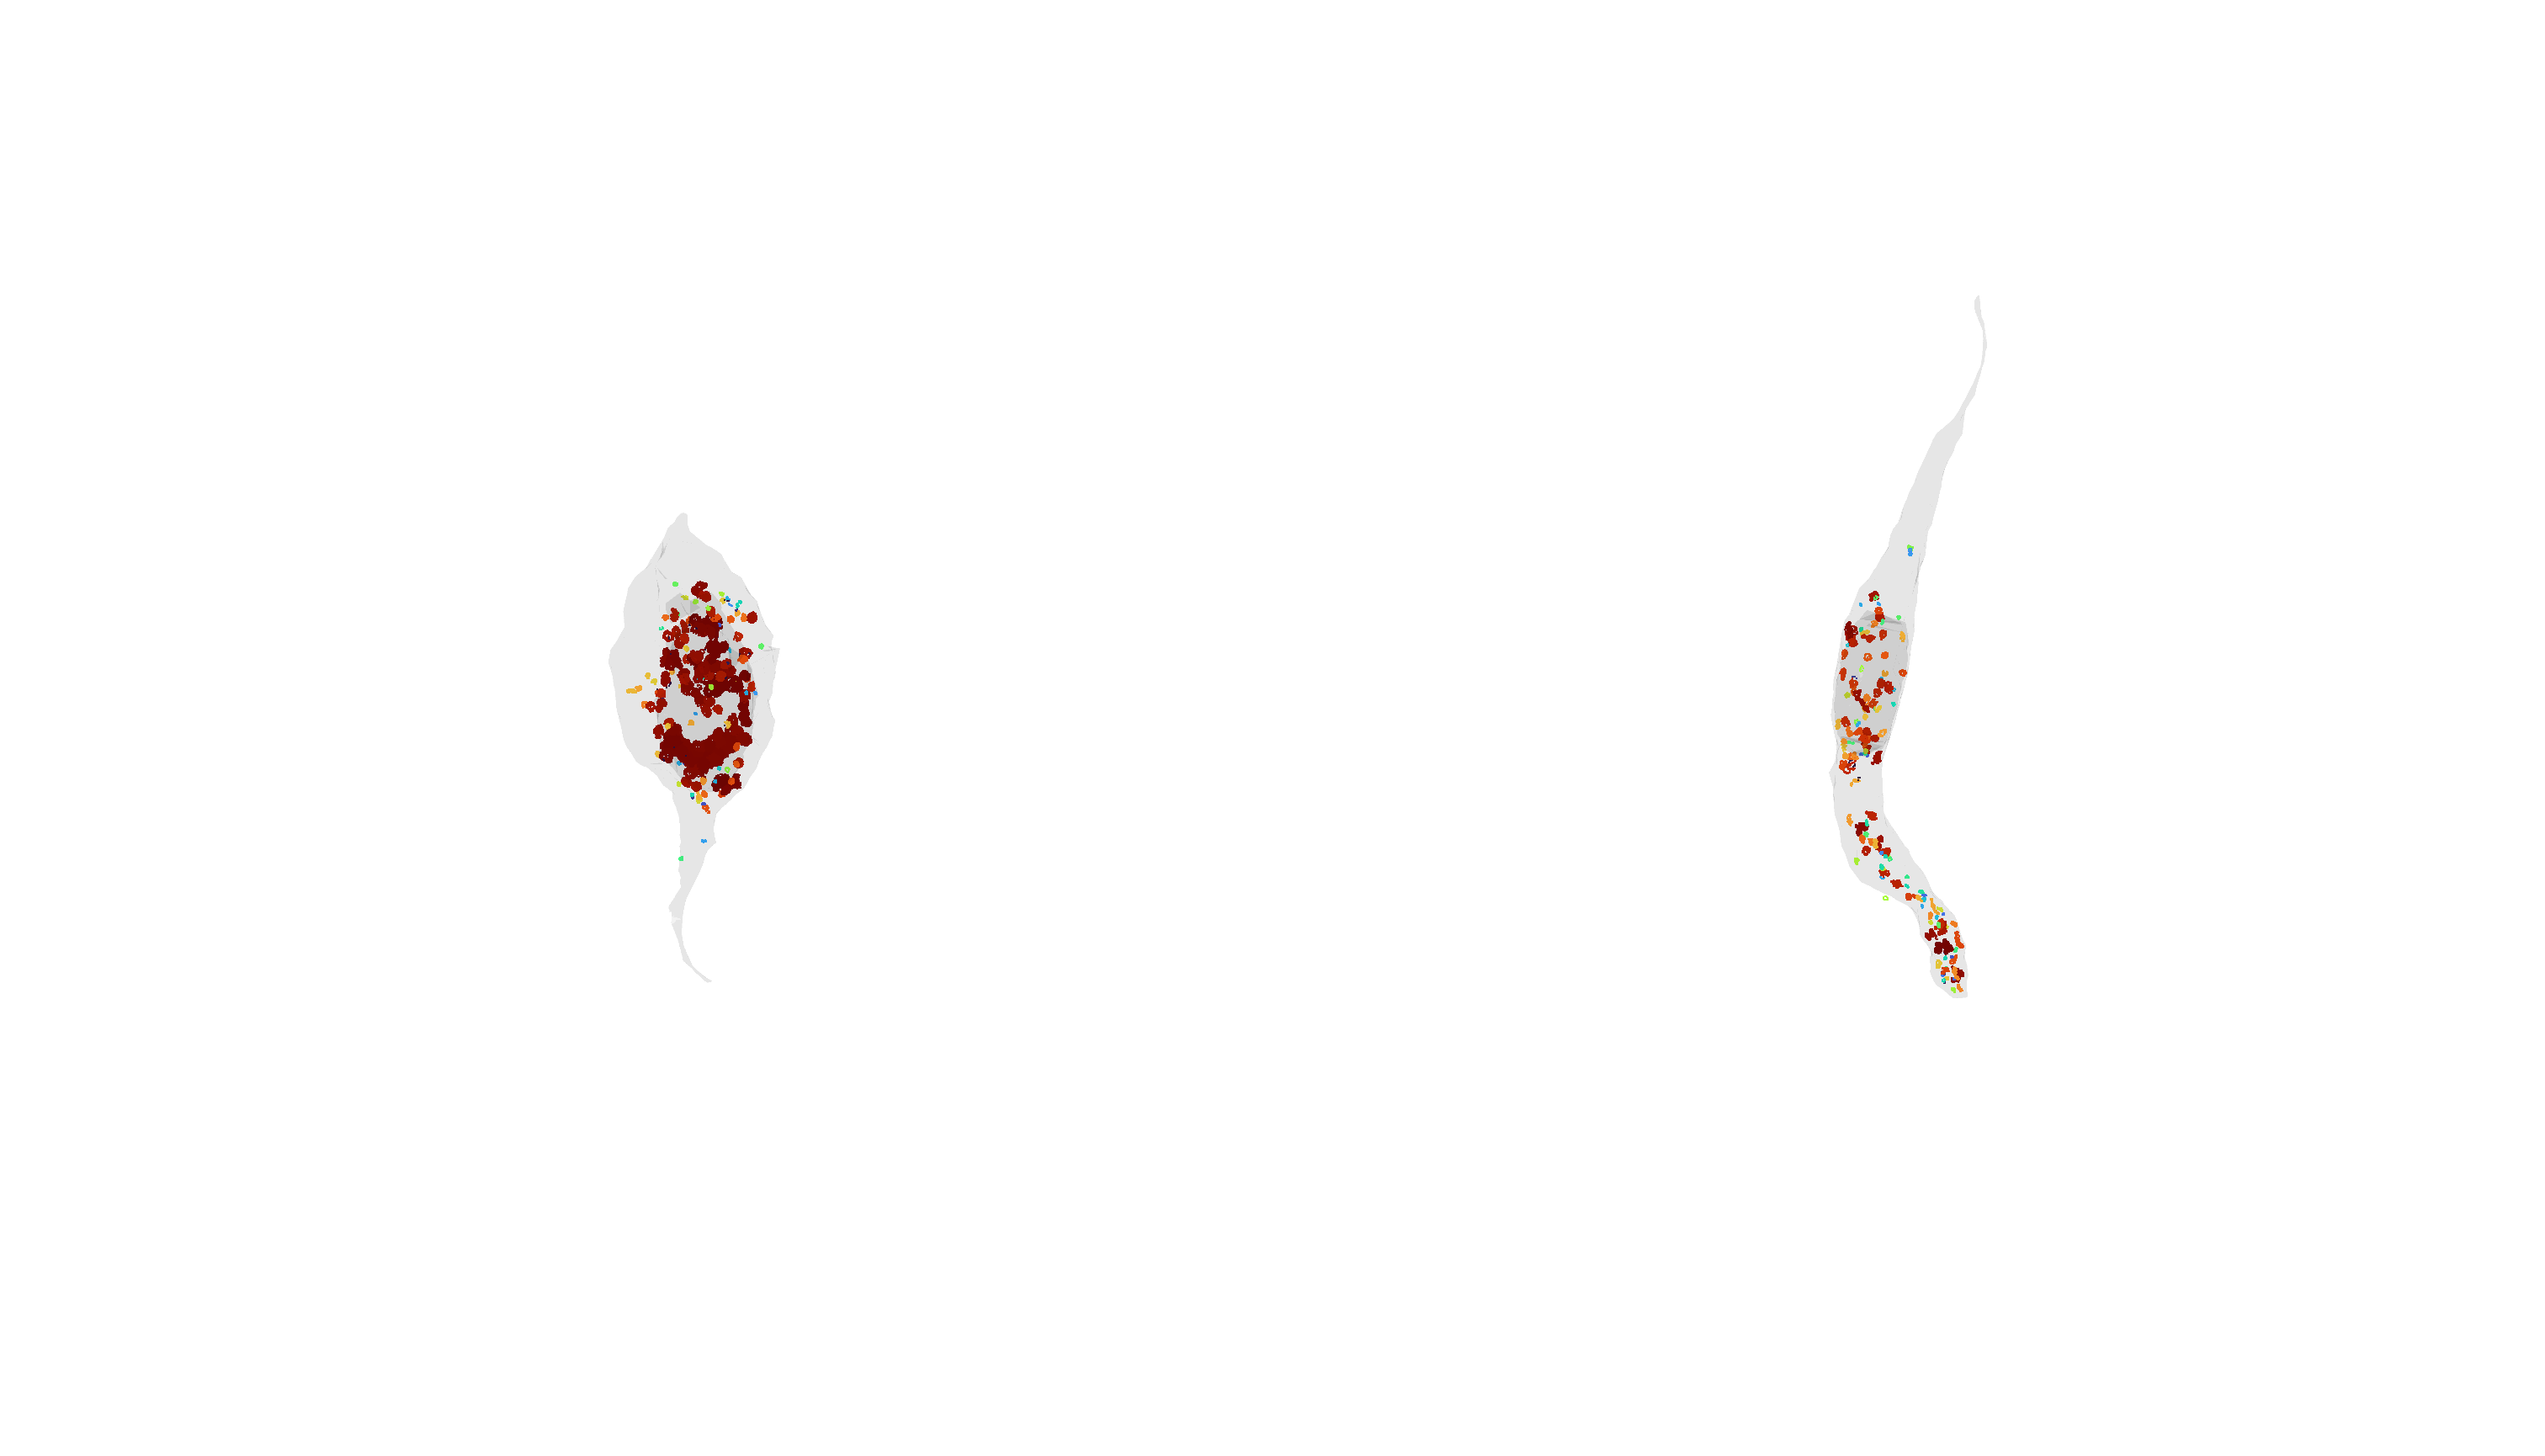


set(gcf,Color='white')

exportgraphics(gcf,fullfile(paths.project,"Lysosome Analysis","Figures","PairedCellsTypeII.png"),Resolution=600)

function ax = plot_cell_mesh(VL,cellT,row)
cm = turbo(max(VL.SizeLabel));

[vCell, vLys, szLys] = getVertsAndAlign(VL, cellT.Cell(row), cellT.Polarity(row)); % align point clouds to cell

pcshow(vLys, szLys,AxesVisibility="off");
hold on

shp = alphaShape(vCell,2);
ax = plot(shp, ...
    FaceColor='k', ...
    FaceAlpha=0.05, ...
    EdgeColor='none');

set(gca,CameraTarget=[0,0,0]);

xlim([-10 10])
ylim([-10 10])
zlim([-50 50])

colormap(cm);

end